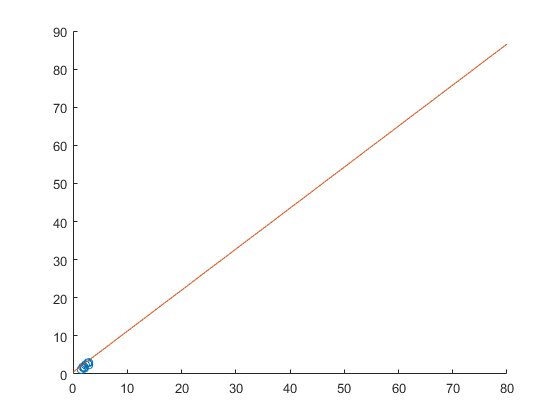

%Problem 1
clear
clc
w = [2.9, 2.1, 2.3, 2.1, 1.8, 2.7, 1.5, 2.9, 1.5];
d = [2.4, 1.5, 2.4, 1.8, 1.8, 2.9, 1.2, 3, 1.2];
x = w;
y = d;
A = [ones(length(x), 1), x'];
b = y';

x_ls = (A' * b) \ (A' * A);
x_vec = linspace(0, 3);

lin_fit = (x_ls(2) * x_vec) + x_ls(1);
scatter(x, y, "o");
hold on;
plot(x_vec, lin_fit);



%problem 2
clear
clc

N = [5, 10, 15, 20]

N =      5    10    15    20


y_0 = 1

y_0 = 1

t_0 = 0

t_0 = 0

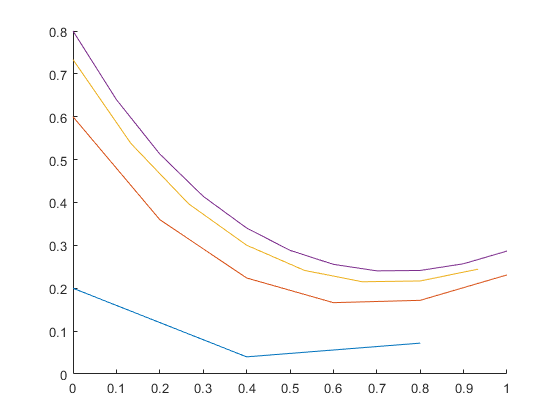

delta_t = 0.4000

sol =     0.2000       NaN       NaN


delta_t = 0.2000

sol =     0.6000       NaN       NaN       NaN       NaN       NaN


delta_t = 0.1333

sol =     0.7333       NaN       NaN       NaN       NaN       NaN       NaN       NaN


delta_t = 0.1000

sol =     0.8000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


figure
hold on
for n = N
    delta_t = 2/n
    y1 = y_0 + delta_t*(-2*y_0 + t_0^2);
    t = 0:delta_t:1;
    sol = NaN(1, length(t));
    sol(1) = y1
    for k = 2 : length(t)
        sol(k) = sol(k - 1) + delta_t*(-2*sol(k - 1) + t(k - 1)^2);
    end
    plot(t, sol)  
end